# Linear Control Design II - Group Work Problem Module 8 

## Description

Figure 1 shows an aircraft in lateral motion where the movements are yaw (rotation around the vertical axis) and roll (rotation around the longitudinal axis). The lateral motion of an aircraft takes primarily place in the horizontal plane. 

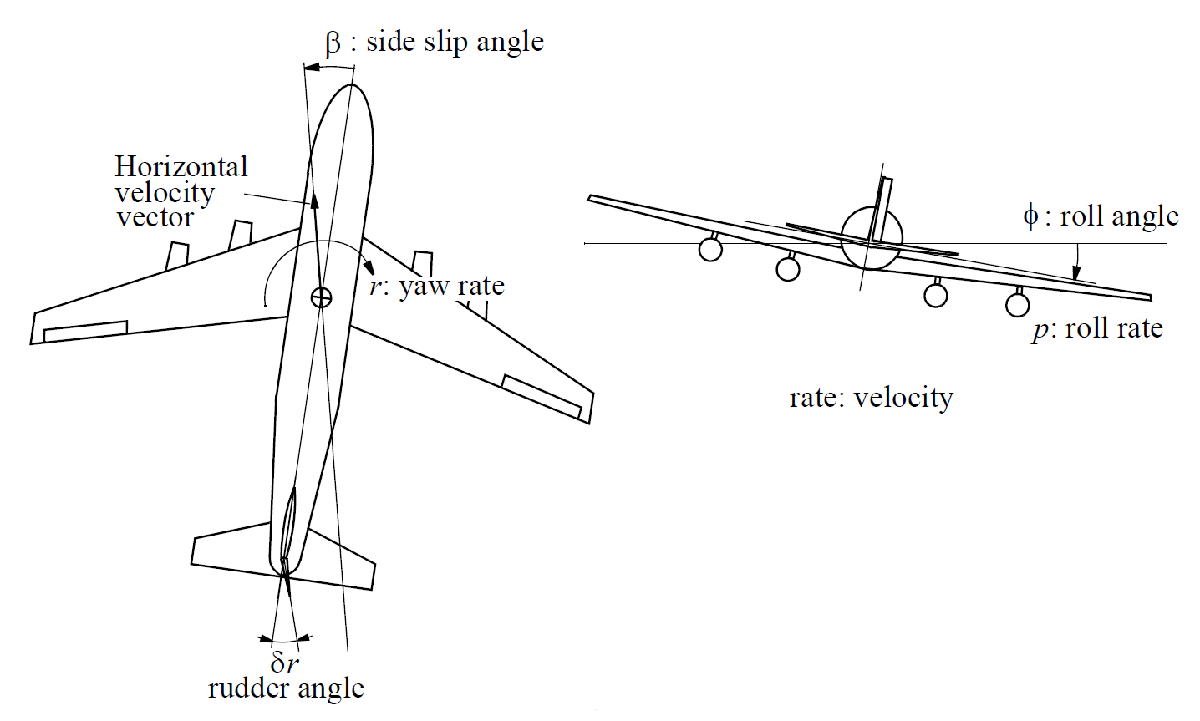  

			Figure 1: Lateral dynamics of a Boeing 747

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:

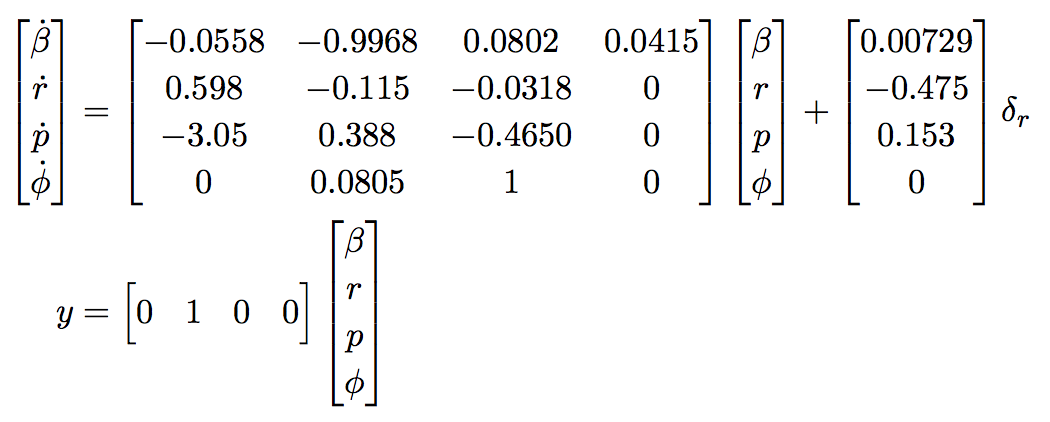

where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), and $\delta_r$ is the rudder deflection (rad). 

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0


B = [0.00729; -0.475; 0.153; 0]

B =     0.0073
   -0.4750
    0.1530
         0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

This assignment guides you through the analysis of the aircraft’s lateral dynamics in terms of natural modes and system responses to non-zero initial conditions and external inputs. 

**Problem 1** 

1) Calculate the eigenvalues of the system dynamical matrix A

2) and based on those identify, if relevant, the time constants, natural frequencies and damping ratios. 

**Solution:**

**1) **The eigenvalues are found by this equation:


$$P_{ch,\mathbf{A}}=det(\lambda\mathbf{I}-\mathbf{A})=0$$


Use Matlab funciton eig(A) to solve it.

% Your solution goes here:
evals = eig(A)

evals =   -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0073 + 0.0000i


Note that all the eigenvalues have negative real parts. It ensures the **asymototic stability** of the system. (What is the **asymptotic stability**???)

**2) **In the case that poles are real, time constants are calcuated by equtation(textbook p47):


$$\tau_i=-\frac{1}{p_i}$$


tau_i = [-1/evals(3) -1/evals(4)]'

tau_i =     1.7773
  137.4010


In the second case, that is, the pole has imaginary part, then the system will have a natural frequency and damping ratio. 


$$\omega_n=\sqrt{\alpha^2+\beta^2},\zeta=-\frac{\alpha}{\sqrt{\alpha^2+\beta^2}}$$


omega_n = abs(evals(1))

omega_n = 0.9472

zeta = -real(evals(1))/omega_n

zeta = 0.0348

Using Matlab function damp(M) can calculate time constants, natural frequency and damping ratio

damp(A) 

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -5.63e-01                 1.00e+00       5.63e-01          1.78e+00    
 -7.28e-03                 1.00e+00       7.28e-03          1.37e+02    


**Problem 2** Based on the calculated eigenvalues determine the natural modes (also known as eigenmodes) of the system and plot their temporal evolution as time goes to infinitiy.

**Solutions:**

The exponential function terms, $e^{\lambda_it}$ are called the natural modes of the system. Thus in our case, they are $e^{-0.00073},\,e^{-0.5627},\,e^{-0.0329\pm0.947i}$

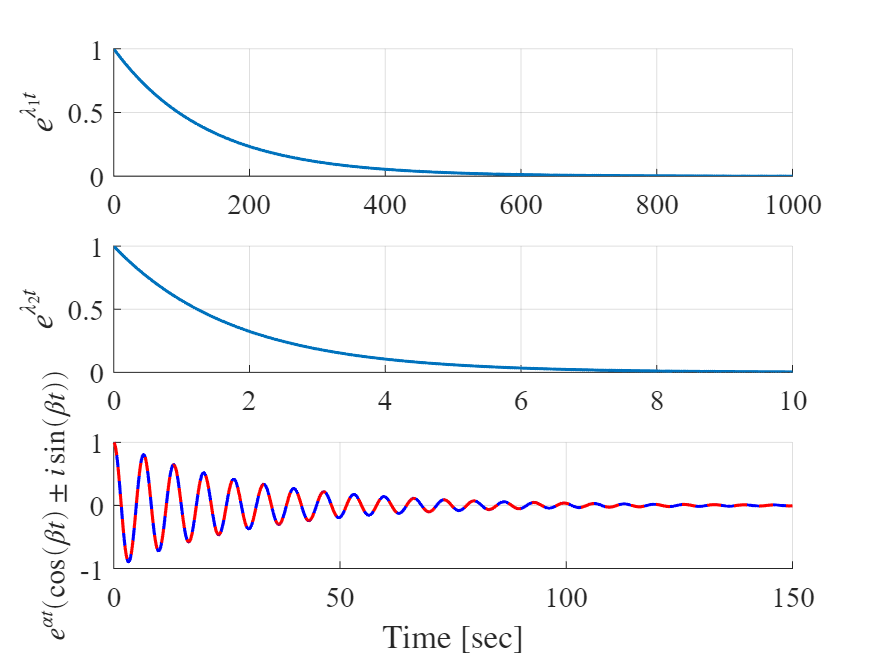

% Plot the temporal evolution of the eigenmodes
%% Why do this??
t_t1 = 0:1:1000;
t_t2 = 0:0.01:10;
t_wn = 0:0.1:150;

% setup natural modes
% e^(lambda*t)
E1 = exp(evals(4)*t_t1); % -0.0073
E2 = exp(evals(3)*t_t2); % -0.5627
E3 = exp(evals(1)*t_wn); % -0.0329+0.9467i
E4 = exp(evals(2)*t_wn); % -0.0329-0.9467i

figure

% plot E1
h1=subplot(3,1,1);
set(h1,'FontSize',14,'FontName','times');
hold on
grid on
plot(t_t1,E1,'LineWidth',1.5);
ylabel('$e^{\lambda_1 t}$','FontSize',16,'FontName','times',"Interpreter","latex");

% plot E2
h2=subplot(3,1,2);
set(h2,'FontSize',14,'FontName','times');
hold on
grid on
plot(t_t2,E2,'LineWidth',1.5);
ylabel('$e^{\lambda_2 t}$','FontSize',16,'FontName','times',"Interpreter","latex");


% plot E3
h3=subplot(3,1,3);
set(h3,'FontSize',14,'FontName','times');
hold on
grid on
plot(t_wn,real(E3),'b',t_wn,real(E4),'--r','LineWidth',1.5);
%ylabel('$e^{(\alpha\pm\betai) t}$','FontSize',16,'FontName','times',"Interpreter","latex");
ylabel('$e^{\alpha t}(\cos(\beta t) \pm i \sin(\beta t))$','FontSize',14,'FontName','times','Interpreter','latex')
xlabel('Time [sec]','FontSize',16,'FontName','times','Interpreter',"latex");

The eigenstructure of the lateral dynamics is usually represented by two real eigenvalues and one pair of complex conjugate eigenvalues. The three lateral modes are referred to as ***roll subsidence***, ***spiral*** and ***dutch roll***. 

- The **roll subsidence** **mode** is non-oscillatory and is usually decoupled from the spiral mode and from the dutch roll modes. In rolling motion the wing experiences a component of velocity normal to the wing resulting in a small increase in the angle of attack on the down- going wing and a small decrease on the up-going wing thus, generating a lift difference over the wing span. Moreover, the lift difference gives rise to a restoring roll moment represented by the roll subsidence mode. 

- The **spiral mode** is usually slow non-oscillatory and involves complex coupled motion in roll, yaw and side-slip angle. The spiral mode is usually excited by a disturbance in side-slip which is typically followed by a disturbance in roll. The side-slip angle generates a force on the tail fin, which in turn generates a yawing moment in the direction of the side-slip angle. The yawing motion generates increased differential lift across the wing span inducing increased roll moment and thereby, aggravates the situation. 

- The** dutch roll mode** is a damped oscillation and the motion is a complex interaction between the three lateral degrees of freedom. The dutch roll mode makes the wing tip move in an elliptic pattern seen from the side parallel to the wing. 

**Problem 3** Based on the found eigenvalues and the aforementioned modes, associate the eigenvalues to the corresponding mode of the lateral dynamics. 	

**Solution:**

From the description, it is clear that **roll subsidence** **mode **and **spiral mode **are non-oscillation modes, thus the **dutch roll mode **is associated with the complex conjugated pair of eigenvalues.

**Dutch Roll Mode: **$e^{-0.0329t}(cos(0.974t) \pm isin(0.974t))$

Spiral mode is described as 'slow' non-oscillatory, thus it has the largest time constant.

**Spiral Mode: **$e^{-0.00073t}$

**Roll subsidence Mode: **$e^{-0.5627t}$

**Problem 4** Compute the modal matrix $\mathbf{M}_{lat}$of the system and discuss which natural modes contributes most and least to the dynamics of the state variables $\beta, r, p, \varphi$ (Make sure that your modal matrix has real elements)	

% Your solution goes here:
[M,E] = eig(A)

M =    0.1994 - 0.1063i   0.1994 + 0.1063i  -0.0172 + 0.0000i   0.0067 + 0.0000i
  -0.0780 - 0.1333i  -0.0780 + 0.1333i  -0.0118 + 0.0000i   0.0404 + 0.0000i
  -0.0165 + 0.6668i  -0.0165 - 0.6668i  -0.4895 + 0.0000i  -0.0105 + 0.0000i
   0.6930 + 0.0000i   0.6930 + 0.0000i   0.8717 + 0.0000i   0.9991 + 0.0000i


E =   -0.0329 + 0.9467i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0329 - 0.9467i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5627 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0073 + 0.0000i


Two of the eigenvectors are compex and conjugates. The real solutions for the system is the cosine with the real part of the complex eigenvector and the sine part with imaginary part of the eigenvector

M_real = [real(M(:,1)),imag(M(:,1)), M(:,3:end)]

M_real =     0.1994   -0.1063   -0.0172    0.0067
   -0.0780   -0.1333   -0.0118    0.0404
   -0.0165    0.6668   -0.4895   -0.0105
    0.6930         0    0.8717    0.9991


The first column shows 

**Problem 5** Determine the transfer function from rudder deflection $\delta_r$ to yaw rate r, and calculate the Bode’s diagram. Which of the aforementioned modes are visible in the magnitude response of the Bode’s diagram?

**Solution:**

The input is $\delta_r$ and the output matrix C already selects the yaw rate $r$as the output. The transfer function can be obtiained by


$$G(s)=C(sI-A)^{-1}B+D$$
		

[num,den] = ss2tf(A,B,C,D);
G = tf(num,den)

G =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



Anotherway is using tf(ltisys)

sys_ss = ss(A,B,C,D);
G = tf(sys_ss)

G =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



Bode Diagram

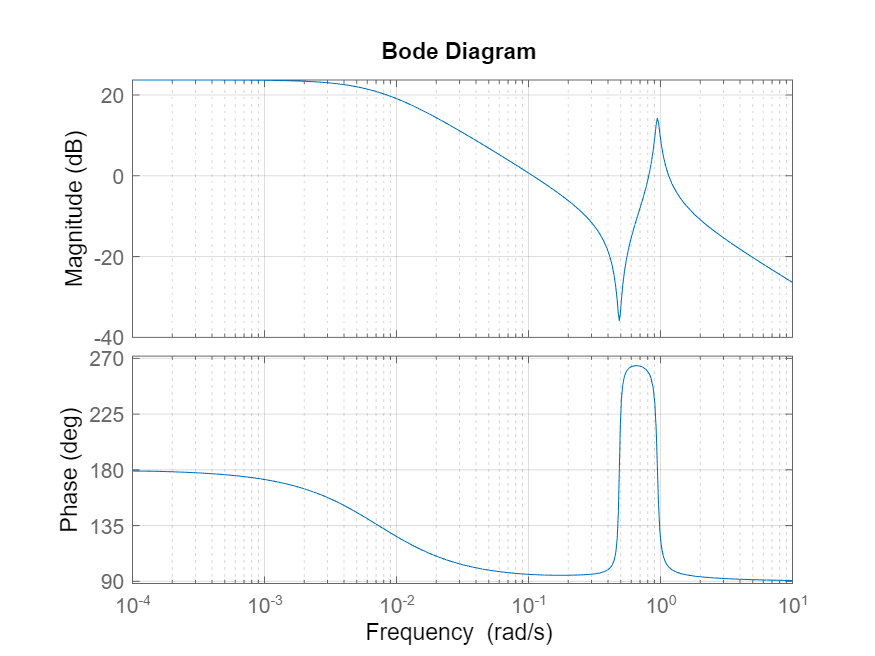

figure
bode(G)
grid on

Can also call bode on the state-space system

figure
bode(sys_ss)
grid on

***(Analysis of Bode Diagram is still need to be done)***

**Problem 6** Calculate the zero-state response for a step of 5 degrees in the rudder input. Analyse the response in connection with the modal analysis. 	

**Solution:**

Now that the transform function is found, it is possible to simulate a step on the rudder angle $\delta_r$ by using the step()-function. The transform function has the initial condition of states as 0 then setp can be directly perform on the transform function.

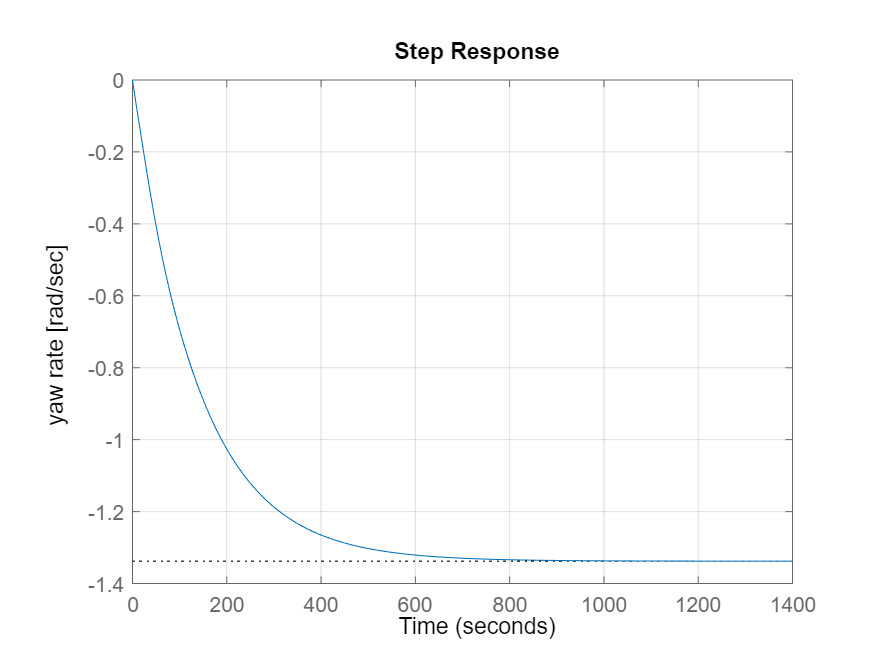

step_magnitude = 5*pi/180; % degree to radius
step(G*step_magnitude)
grid on
ylabel('yaw rate [rad/sec]');

**Problem 7** Calculate the zero-input response for a side-slip initial angle $\beta_0 = 1$degree. Analyse the response in connection with the modal analysis. 	

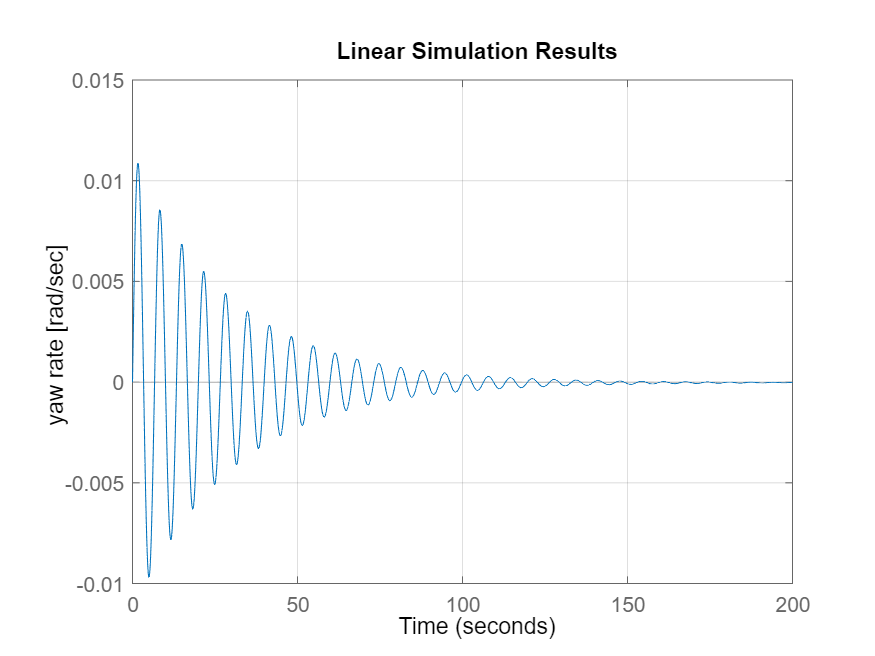

figure
t = 0:0.1:200;
u = zeros(length(t),1);
beta0 = 1*pi/180; % degree2radius
x0 = [beta0 0 0 0]';
lsim(A,B,C,D,u,t,x0)
grid
ylabel('yaw rate [rad/sec]');

**Problem 8** Calculate the zero-state response for the rudder deflection shown in the figure below and discuss the aircraft’s dynamical behaviour during these manoeuvres. 

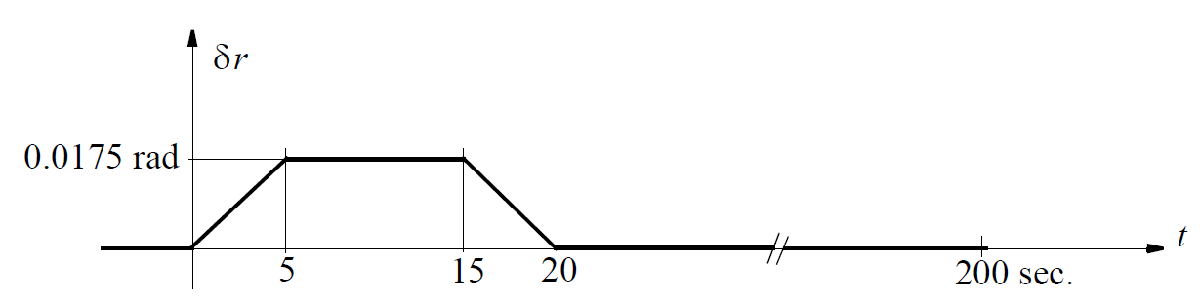

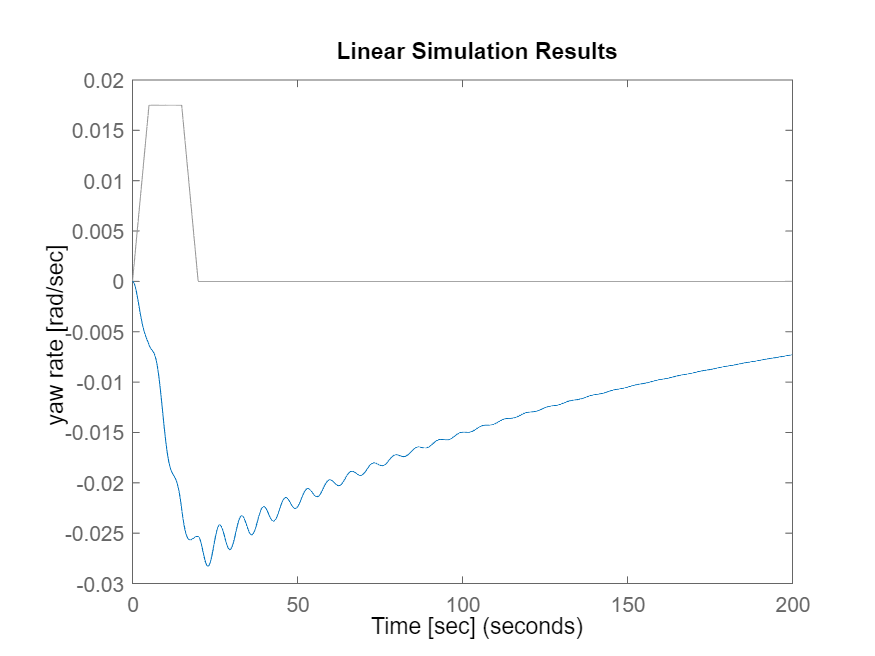

% Your solution goes here:
figure
t = 0:0.1:199.9;
ut1 = (0:50) * 0.0175/50; % Rising Ramp
ut2 = ones(1,98) * 0.0175; % Steady value of 1
ut3 = (0:50) * (-0.0175/50) + 0.0175; % Decreasing ramp
ut4 = zeros(1,1800); % Steady value of 0
uttot = [ut1 ut2 ut3 ut4]; % Rudder time function
x0 = [0 0 0 0]';
lsim(A,B,C,D,uttot,t,x0)
ylabel('yaw rate [rad/sec]');
xlabel('Time [sec]')